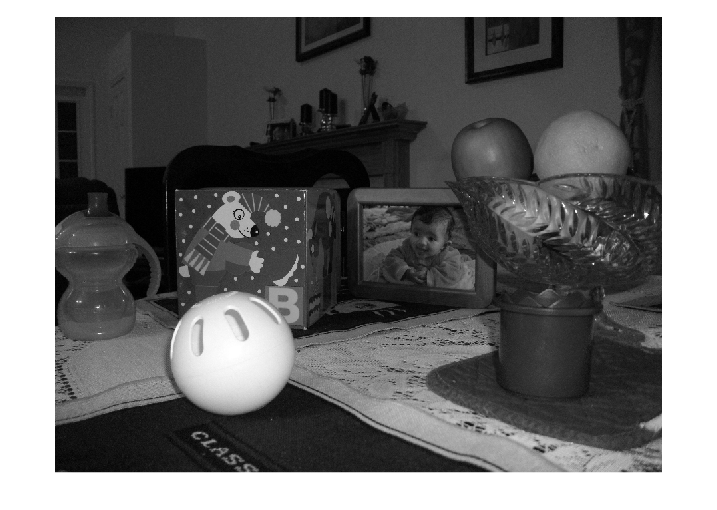

clear;
image = imread('toysflash.png');
image = im2double(image);
image = rgb2gray(image);
imshow(image);

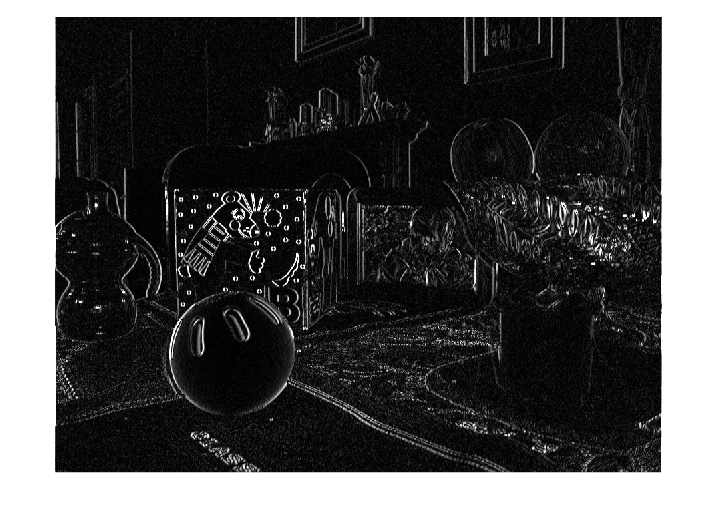

% To make it easier to compute gradient, we grayscale image

% Define special kernel
sob = [-1 0 1; -2 0 2; -1 0 1];
% "Center is (2,2), and computes kernel by taking difference with
% neighbours. By going one row & column both up and down, it's less
% suseptible to noise."
gradx = imfilter(image, sob);
imshow(abs(gradx)); % Take abs so we can see all edges no matter direction

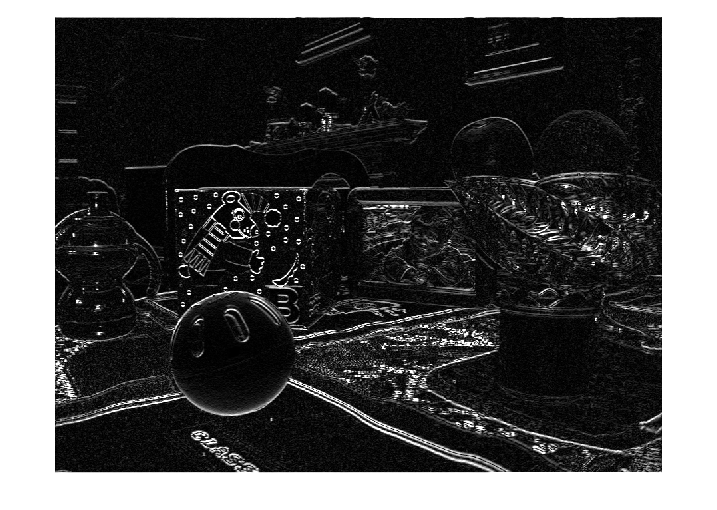

% These are edges in x direction, and diagonal (varying in x & Y)
grady = imfilter(image, sob');
imshow(abs(grady));

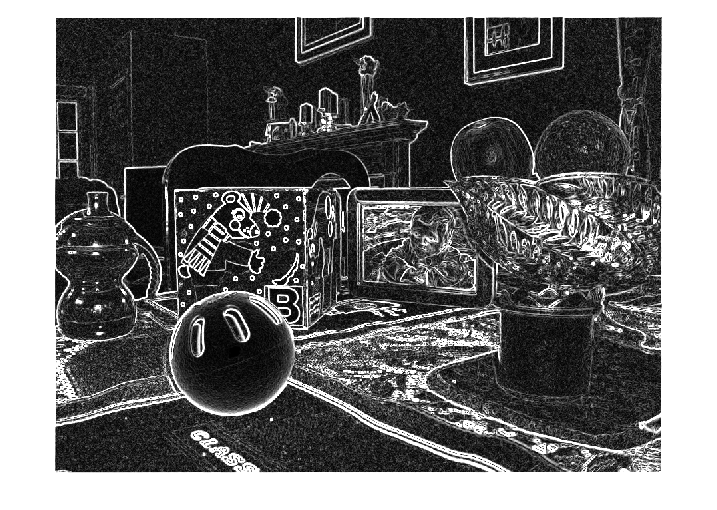


% 2D image, so we can define two kernels. To see in both directions, we use
% the gradient.
gradmag = sqrt(gradx.^2 + grady.^2);
imshow(2*gradmag) % The factor of 2 makes edges brighter. So we can see noise 

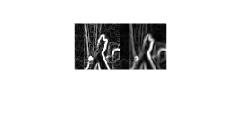


% So lets make guassian kernel to denoise 
gausk = fspecial('gaussian', 5,  1);
smoothed = imfilter(image, gausk);
smoothgrad = sqrt(imfilter(smoothed, sob).^2 + imfilter(smoothed, sob').^2);
imshow(2*[gradmag(100:150, 450:500) smoothgrad(100:150, 450:500)])

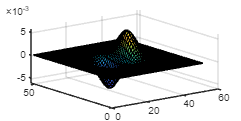

% As we can see, left picture is getting rid of noise.

% Let us somewhat simplify by taking derivative of gaussian filter 
surf(conv2(fspecial('gaussian', 50 ,5), sob)); % This is a large sample derivative kernel. 

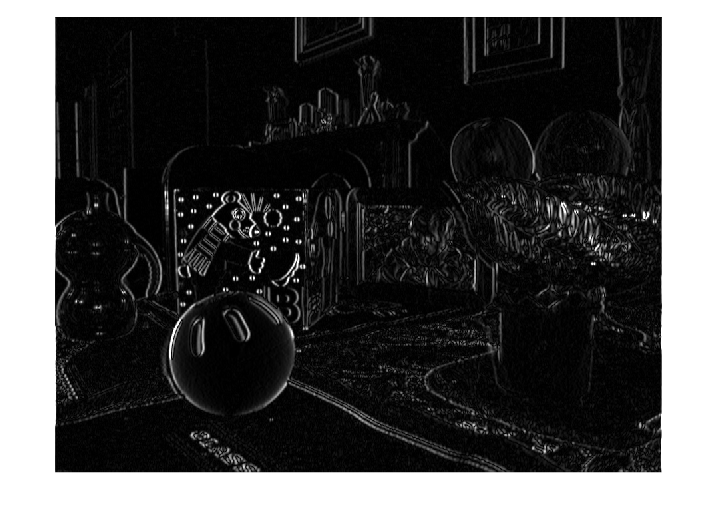

% gausk is same type but fewer edges make surface jagged 
imshow(abs(imfilter(image, conv2(gausk, sob))))

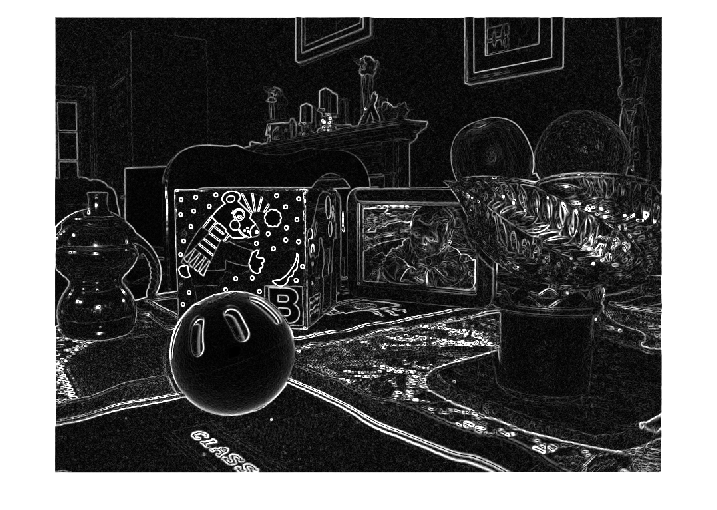

imshow(gradmag); % In this picture, the edges are multiple pixels. In reality we don't need this and we only need one pixel per edge

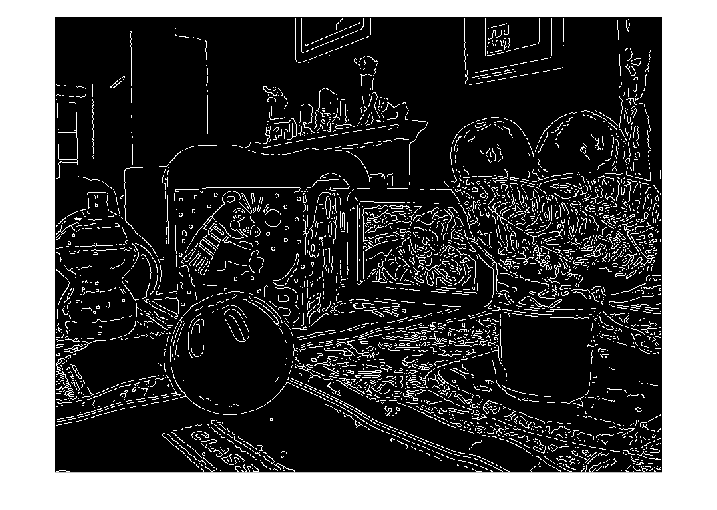


% Now lets talk about Canny edge operation. 
% For a given pixel, Canny edge detection will look at gradient for that
% pixel. Essentially asks "Is this pixel larger than my neighbours?"
% This is computing local maxima and minima 
% It also has a two-threshold system. One threshold is a very large value,
% so edge larger than all other edges. The second lower threshold marks
% probable edges. 
% When Canny edge detection does this alghorithm for all pixels, we get
% edges marked by the two threshold boundary and noise edges. 
% When it composes the two threshold edges, it checks if the lower probable
% threshold edges have a definite higher threshold neighbour. If yes, it
% marks the two edges together as one edge.
[cannyedge, thresh] = edge(image, 'canny');
imshow(cannyedge);


% Now let's change parameters by increasing higher threshold
thresh

thresh =     0.0250    0.0625


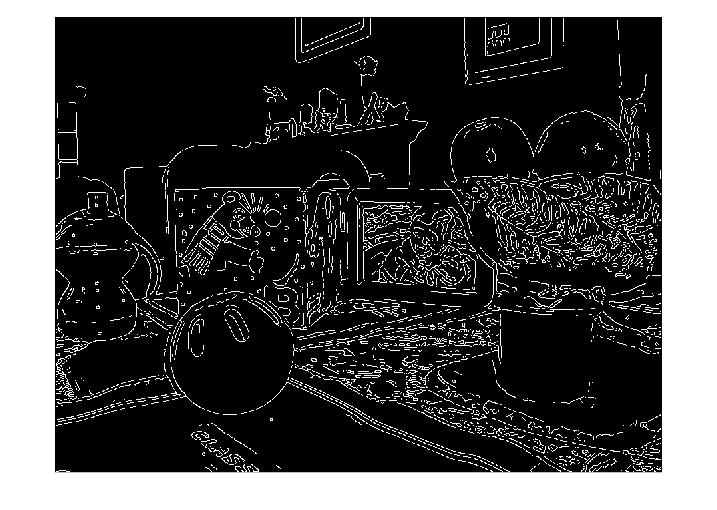

imshow(edge(image, 'canny', [0.05 0.08])) % Now we won't see as much edges 

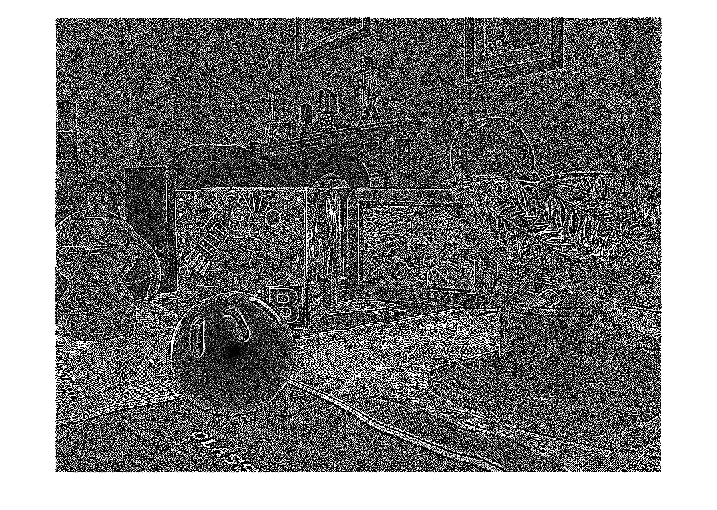

% We can also change smoothness as last argument in edge call 

% We have been detecting two different gradients in each direction to get
% edges. We can use laplacian to simplify into one operation, but this
% creates alot of noise. So we can filter first with gaussian. 
% But instead, we compute laplacian of gaussian and then apply to image to
% find edges
lapkern = [0 -1 0; -1 4 -1; 0 -1 0];
imshow(20*imfilter(image, lapkern)); % SO much noise!

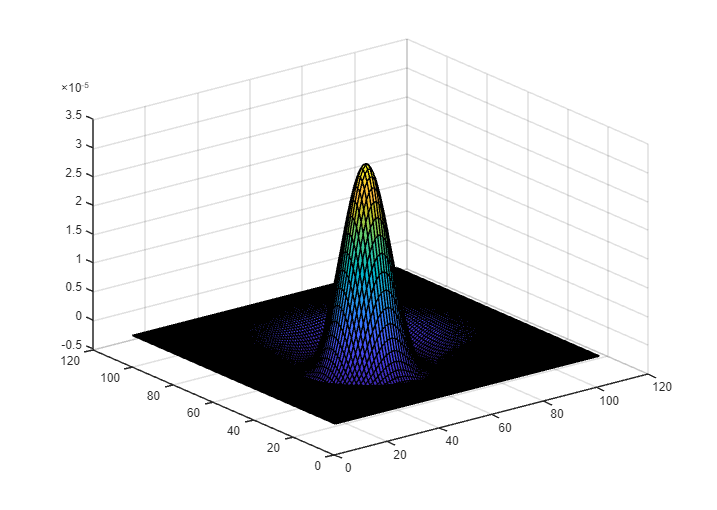

% Alot of zero crossing in second derivative
surf(conv2(fspecial('gaussian', 100, 10), lapkern)); % This is our gaussian of lapacian (alot of edges, more than w eneed)

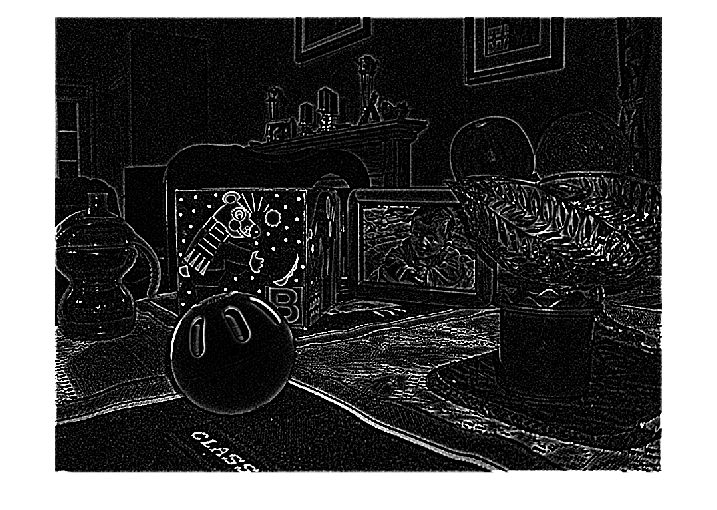

logkern = conv2(gausk, lapkern);
imshow(20*imfilter(image, logkern));